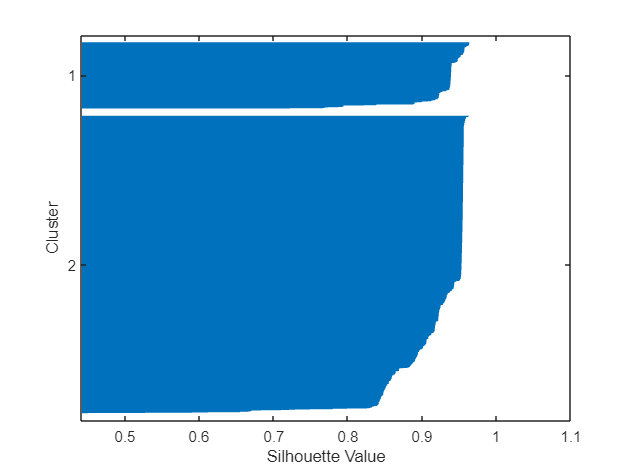

ans = 0.9256

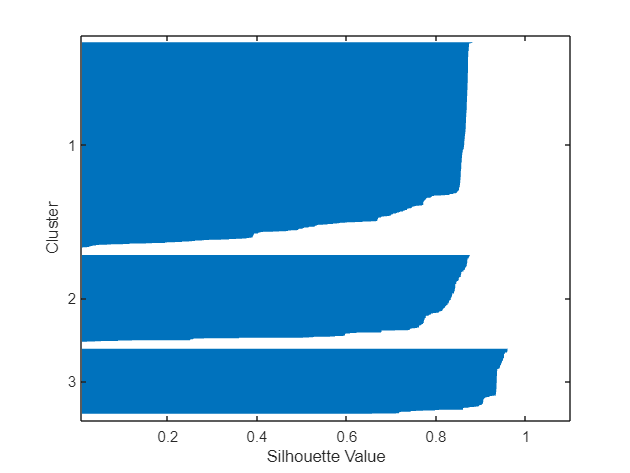

ans = 0.8073

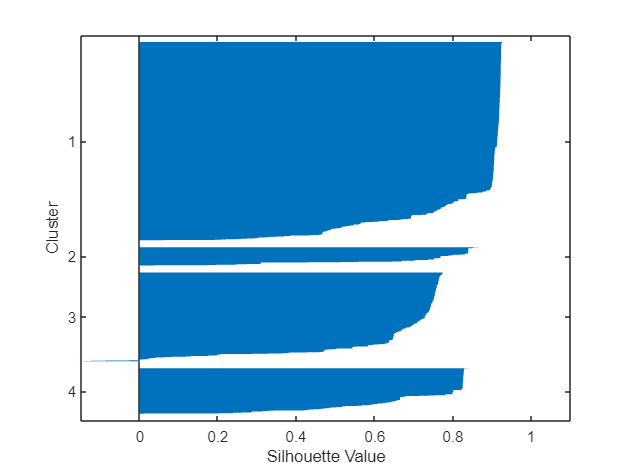

ans = 0.7702

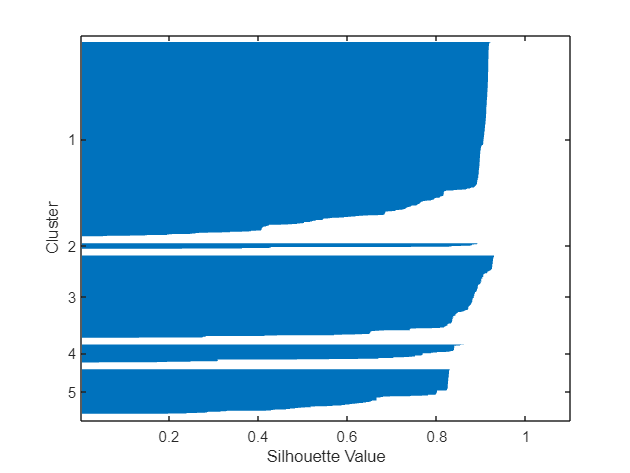

ans = 0.8126

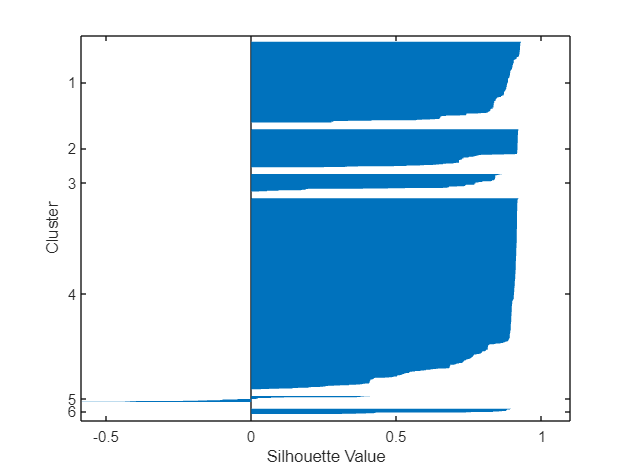

ans = 0.8133

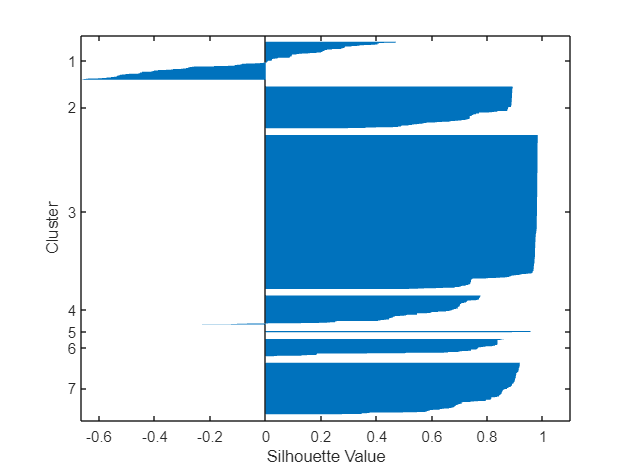

ans = 0.7486

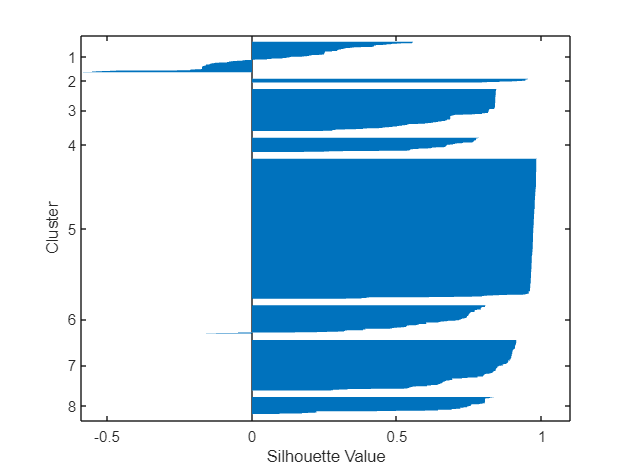

ans = 0.7652

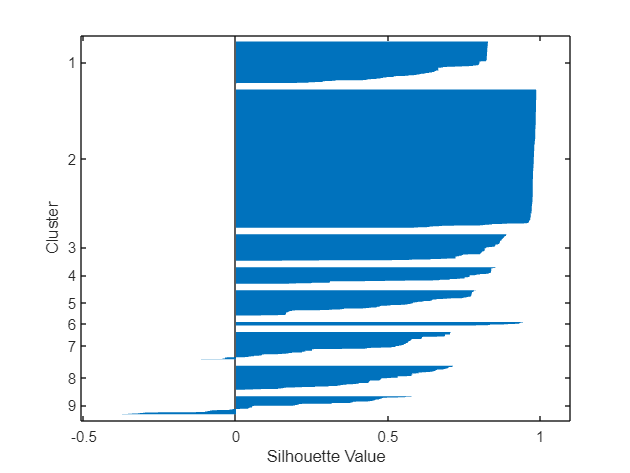

ans = 0.7440

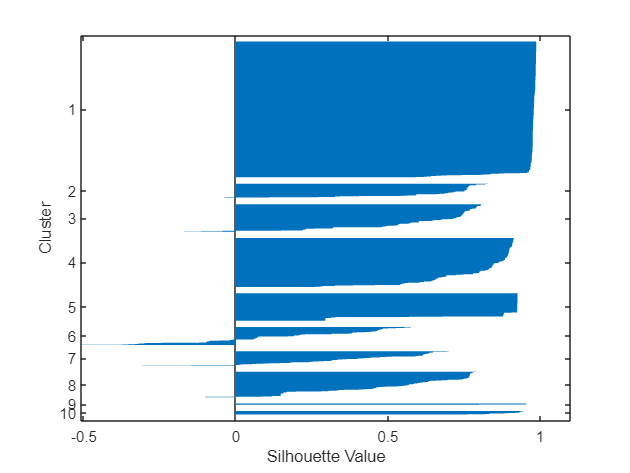

ans = 0.7772

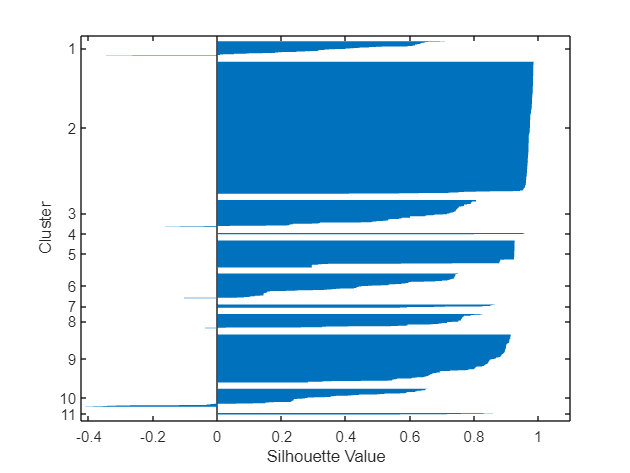

ans = 0.7747

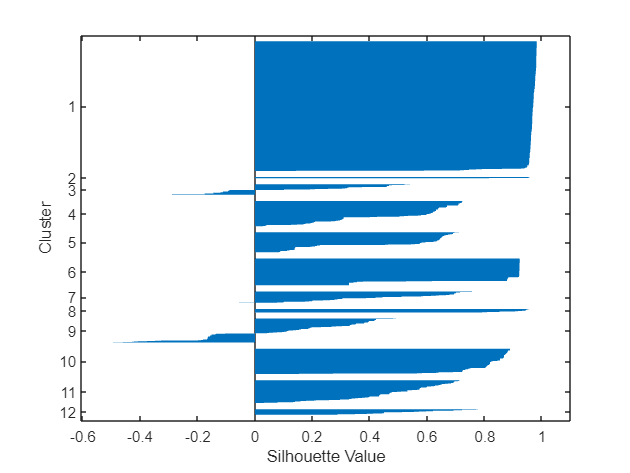

ans = 0.7055

%cleaning workspace
clear;

% Load dataset
load Dataset_task2.mat;
%Dataset presenta dati mancanti o errati e colonna 19 duplicata di 18
short_matrix_no_id(:,19) = [];
short_matrix_no_id = fillmissing(short_matrix_no_id,"knn");
short_matrix_no_id(:,[2:4]) = normalize(short_matrix_no_id(:,[2:4]), 'range', [0, 1]);
short_matrix_no_id(:,[5,9:15,18]) = zscore(short_matrix_no_id(:,[5,9:15,18]));

% BUS LINE
bus_line = short_matrix_no_id(:,[1, 2:6, 8:9, 15, 16:17]);

%Vehicle ID
vehicle_id = short_matrix_no_id(:,[1, 6:8, 11:15, 18]);

%driver id
driver_id = short_matrix_no_id(:, [1, 6, 8, 15]);

% Calcolo del numero di cluster
unique_driver = unique(short_matrix_no_id(:,8),"rows"); %229 istanze
unique_vehicle = unique(short_matrix_no_id(:,6),"rows"); %105 istanze
unique_line = unique(short_matrix_no_id(:,1),"rows"); % 87 istanze


% Range of number of clusters
k_values = 2:12;

% Initialize array to store percentage variance for each matrix
variance_pct_driver = zeros(size(k_values));
variance_pct_vehicle = zeros(size(k_values));
variance_pct_busline = zeros(size(k_values));
mean_silhouette_scores = [];
% Perform k-means clustering for each number of clusters on driver_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on driver_id
    [idx_driver, centroids, sumd] = kmeans(driver_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_driver(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(driver_id,idx_driver);
    silhouette(driver_id,idx_driver);

    mean(sil_scores)
    
end

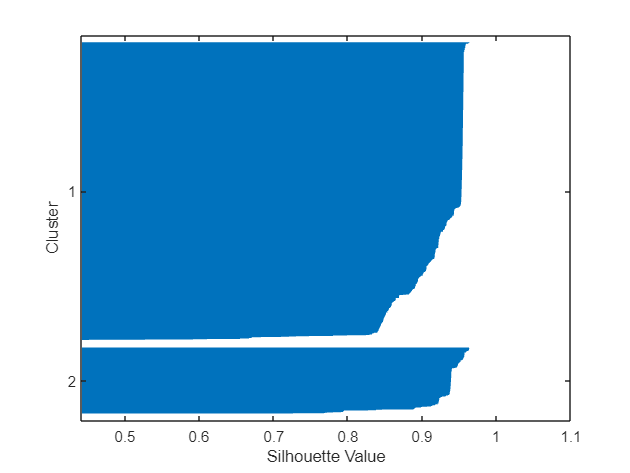

ans = 0.9256

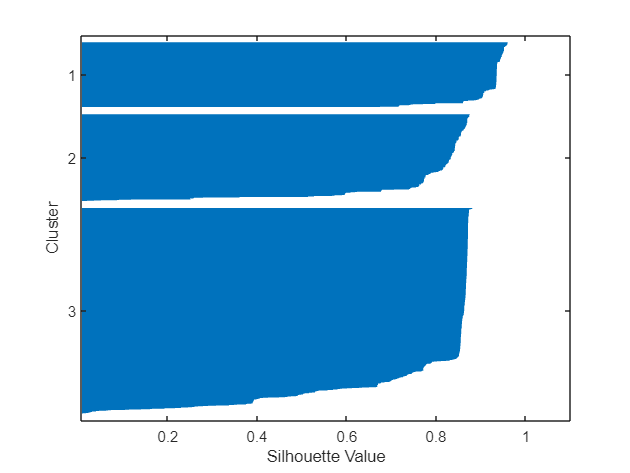

ans = 0.8073

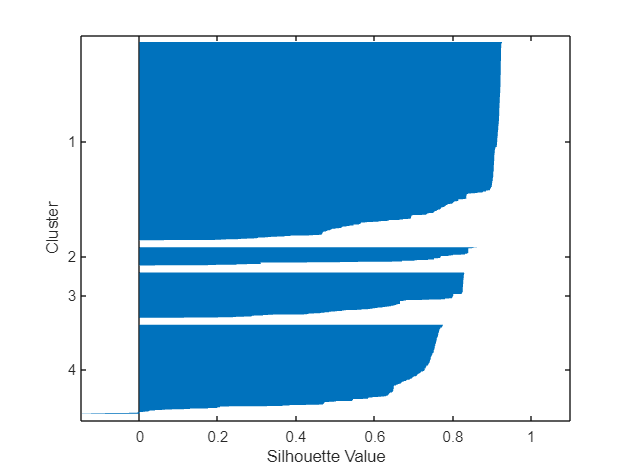

ans = 0.7702

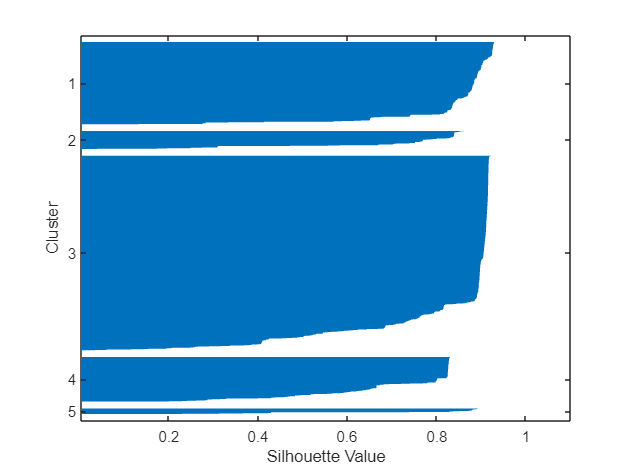

ans = 0.8126

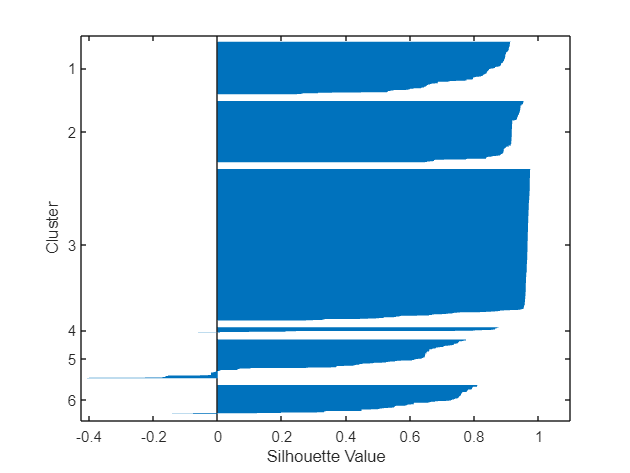

ans = 0.8239

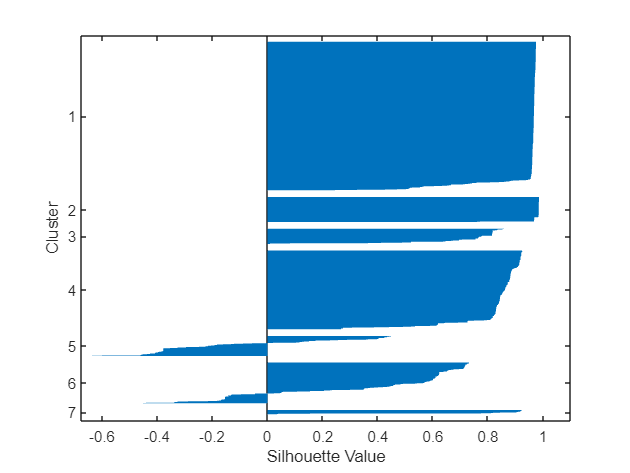

ans = 0.7739

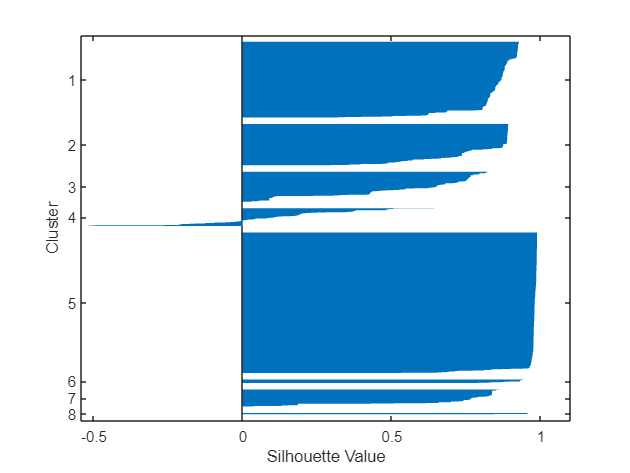

ans = 0.8165

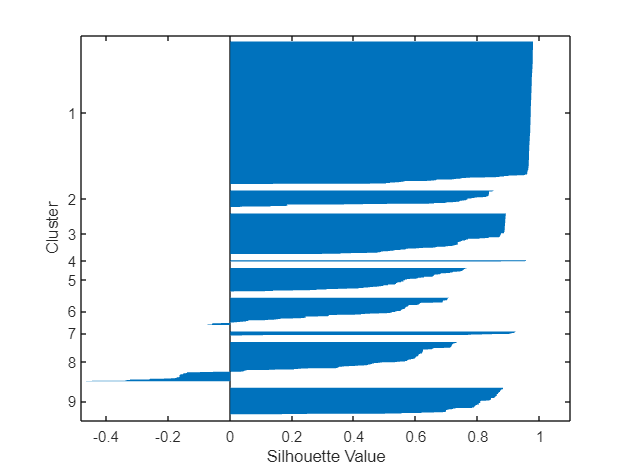

ans = 0.7552

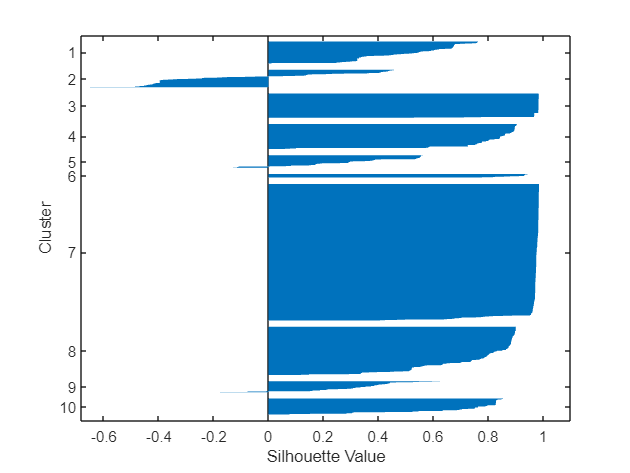

ans = 0.7666

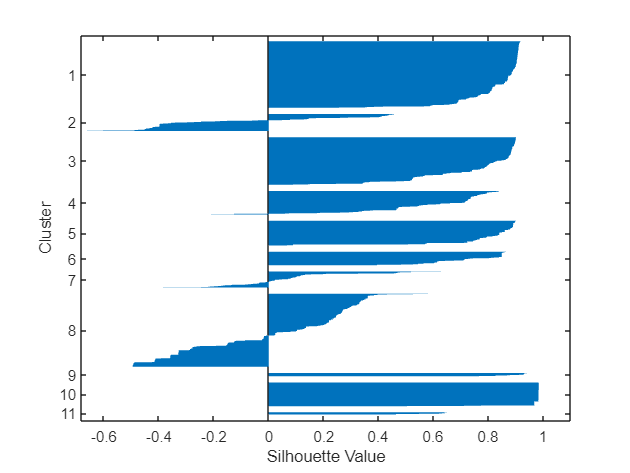

ans = 0.5223

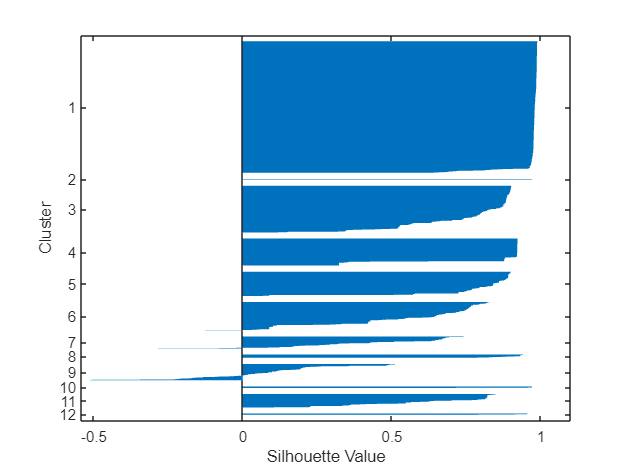

ans = 0.7867


% Perform k-means clustering for each number of clusters on vehicle_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on vehicle_id
    [idx_vehicle, centroids, sumd] = kmeans(vehicle_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_vehicle(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(vehicle_id,idx_vehicle);
    silhouette(vehicle_id,idx_vehicle);
    mean(sil_scores)
    
end

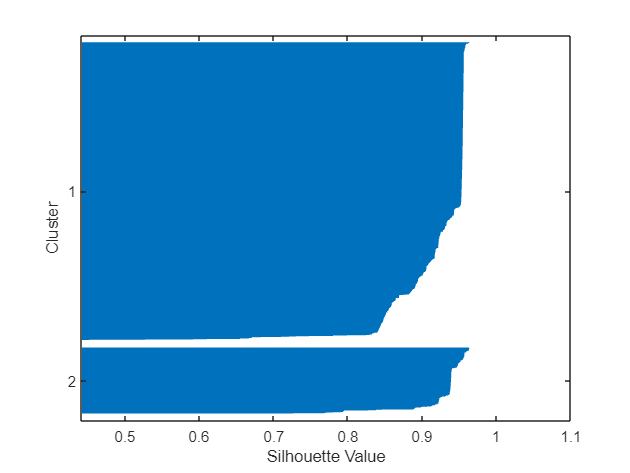

ans = 0.9256

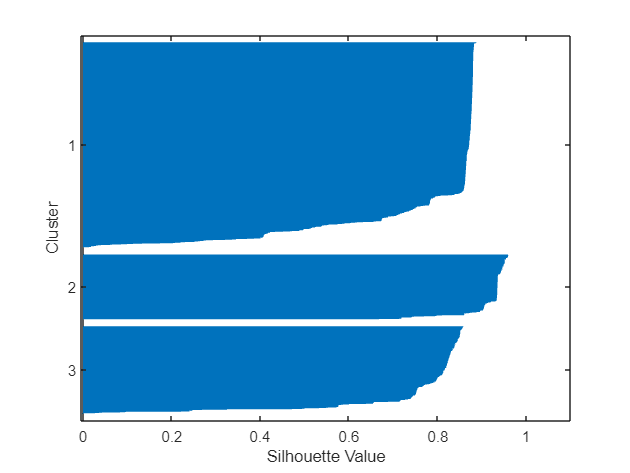

ans = 0.8083

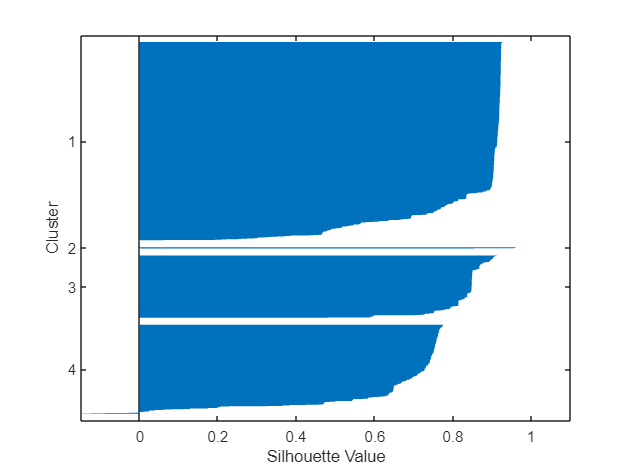

ans = 0.7933

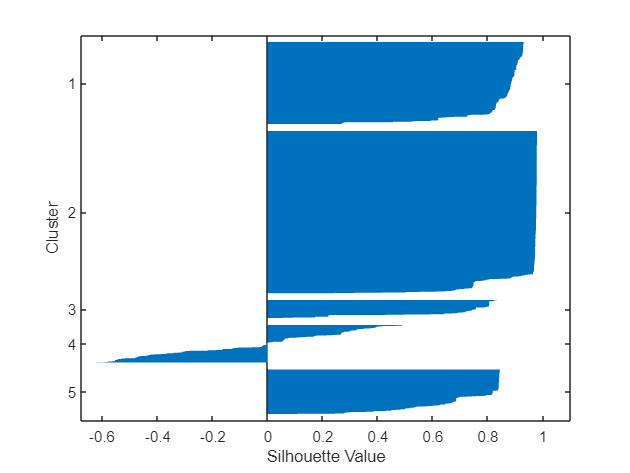

ans = 0.7712

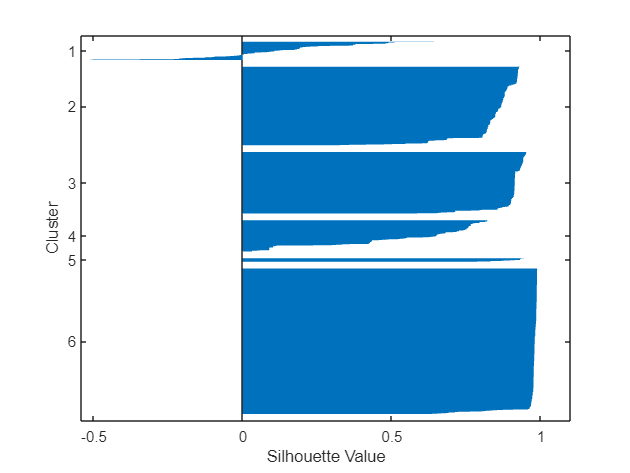

ans = 0.8426

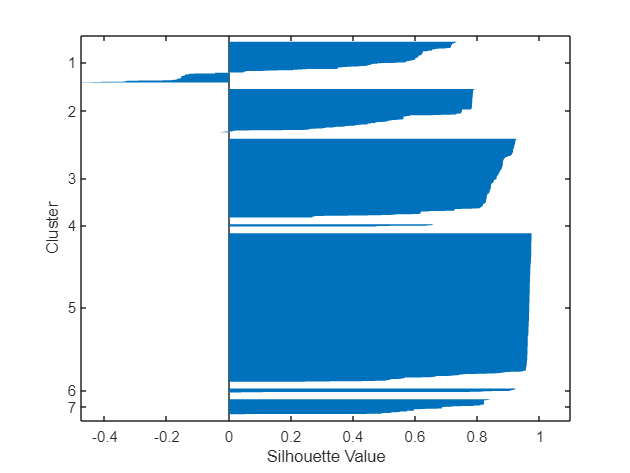

ans = 0.7906

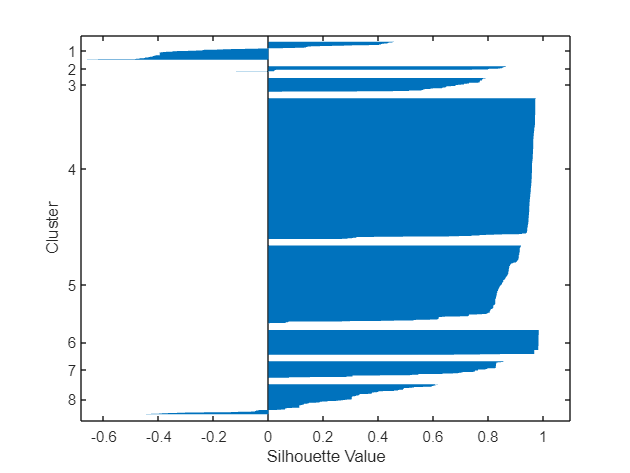

ans = 0.7627

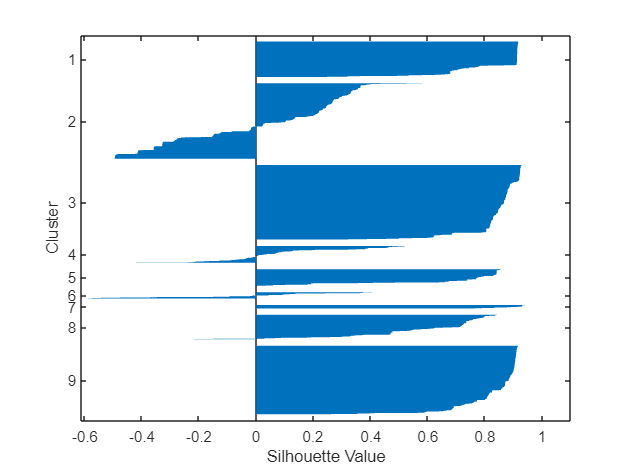

ans = 0.5635

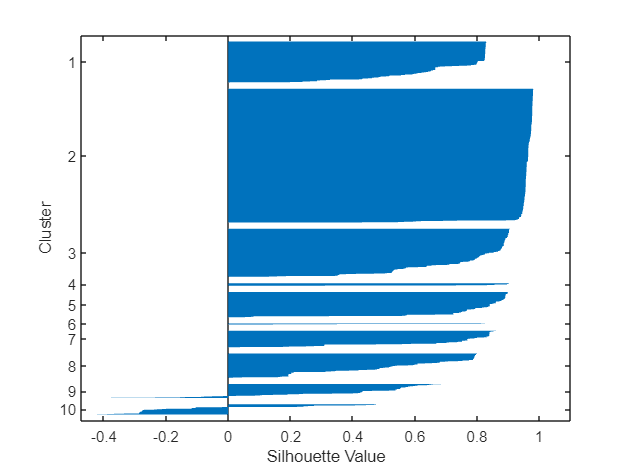

ans = 0.7747

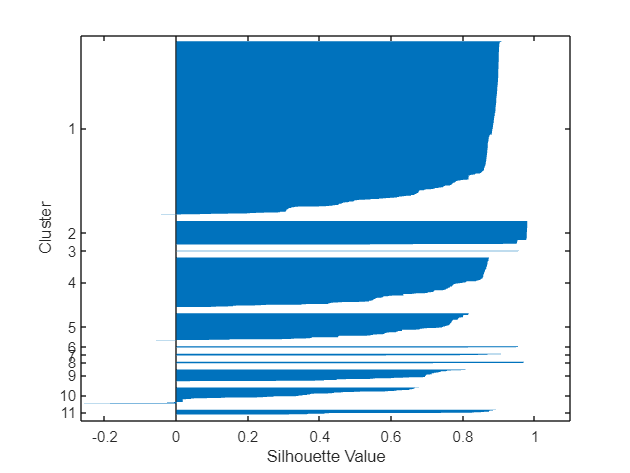

ans = 0.7656

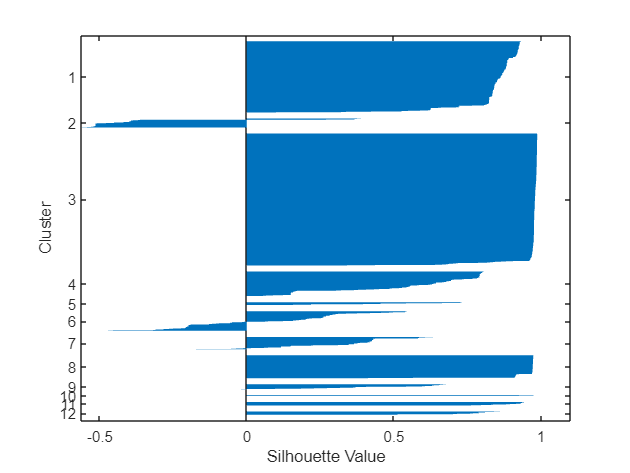

ans = 0.7675


% Perform k-means clustering for each number of clusters on bus_line
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on bus_line
    [idx_line,centroids, sumd] = kmeans(bus_line, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_busline(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(bus_line,idx_line);
    silhouette(bus_line,idx_line);
    mean(sil_scores)
end

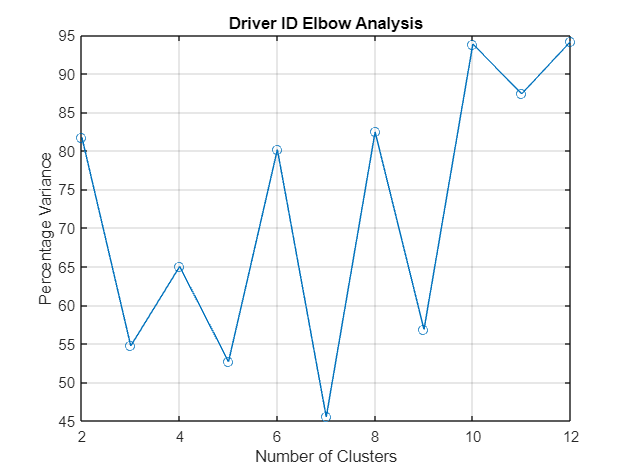


% Plot elbow curves for each matrix separately
figure;
plot(k_values, variance_pct_driver, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Driver ID Elbow Analysis');
grid on;

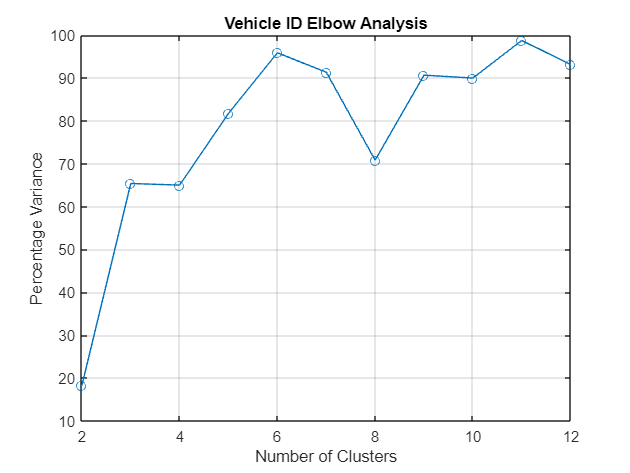


plot(k_values, variance_pct_vehicle, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Vehicle ID Elbow Analysis');
grid on;

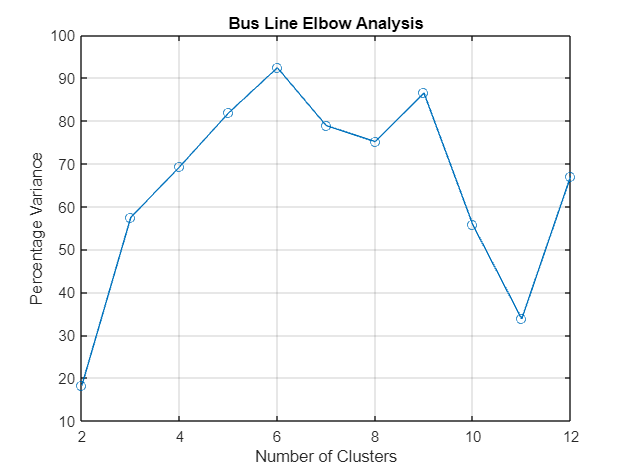


plot(k_values, variance_pct_busline, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Bus Line Elbow Analysis');
grid on;



idx_line = kmeans(bus_line, 5);
idx_vehicle = kmeans(vehicle_id, 6);
idx_driver = kmeans(driver_id, 5);

% Assign a new ID to each cluster
cluster_line_ids = (1:5)';
cluster_vehicle_ids = (1:6)';
cluster_driver_ids = (1:5)';


% Assign a new ID to each cluster
new_ids_line = cluster_line_ids(idx_line);
new_ids_vehicle = cluster_vehicle_ids(idx_vehicle);
new_ids_driver = cluster_driver_ids(idx_driver);

% Replace the original IDs in the dataset with the new IDs
short_matrix_no_id = [short_matrix_no_id, new_ids_line new_ids_vehicle new_ids_driver];
X = short_matrix_no_id;
X(:, [1,6,8]) = [];
Y = short_matrix_no_id(:,15);
% Split data into training and testing sets
train_ratio = 0.7;
train_size = round(train_ratio*size(X,1));
train_idx = randperm(size(X,1),train_size);
test_idx = setdiff(1:size(X,1),train_idx);
X_train = X(train_idx,:);
Y_train = Y(train_idx,:);
X_test = X(test_idx,:);
Y_test = Y(test_idx,:);


% Define neural network
input_size = size(X_train,2);
output_size = 1;
hidden_size = 12;
net = fitnet(hidden_size);
net.trainFcn = 'trainbr'; % Bayesian regulation algorithm
net.divideFcn = 'dividerand'; % Random division of data into training and validation sets
net.divideParam.trainRatio = 0.2; % Training set proportion
net.divideParam.valRatio = 1 - net.divideParam.trainRatio; % Validation set proportion
net.divideParam.testRatio = 0; % No testing set
net.trainParam.max_fail = 20; % Maximum validation failures
net.trainParam.epochs = 5; % Maximum number of epochs
net.trainParam.goal = 1e-5; % Training goal
net.performFcn = 'mse'; % Mean squared error performance function

% Train neural network
avg_accuracy = 0;
avg_MSE = 0

avg_MSE = 0

avg_COV = 0

avg_COV = 0

n_cycle=50

n_cycle = 50

for i = 1:n_cycle
    [net,tr] = train(net,X_train',Y_train');
    
    % Test neural network
    Y_pred = net(X_test');
    
    % Display the covariance matrix and error
    covariance_matrix = cov(Y_pred,Y_test);
    covariance_matrix
    % Calculate the covariance error
    cov_error = sum(sum((cov(Y_pred) - Y_test).^2));
    acc = mean(abs(Y_pred-Y_test')<0.05);

    avg_accuracy = avg_accuracy + acc;
    avg_MSE = avg_MSE + mse(net,Y_pred,Y_test');
    avg_COV = avg_COV + cov_error
end

covariance_matrix =     0.8764    0.9404
    0.9404    1.0094


avg_COV = 5.3161e+03

covariance_matrix =     1.0091    1.0093
    1.0093    1.0094


avg_COV = 1.1381e+04

covariance_matrix =     1.0088    1.0091
    1.0091    1.0094


avg_COV = 1.7444e+04

covariance_matrix =     1.0091    1.0093
    1.0093    1.0094


avg_COV = 2.3509e+04

covariance_matrix =     1.0090    1.0092
    1.0092    1.0094


avg_COV = 2.9574e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 3.5639e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 4.1705e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 4.7771e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 5.3837e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 5.9902e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 6.5968e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 7.2034e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 7.8099e+04

covariance_matrix =     1.0092    1.0093
    1.0093    1.0094


avg_COV = 8.4165e+04

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 9.0232e+04

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 9.6299e+04

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.0237e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.0843e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.1450e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.2057e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.2663e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.3270e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.3877e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.4483e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.5090e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.5697e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.6303e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.6910e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.7517e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.8123e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.8730e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.9337e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 1.9943e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.0550e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.1157e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.1763e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.2370e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.2977e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.3583e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.4190e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.4797e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.5403e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.6010e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.6617e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.7223e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.7830e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.8437e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.9043e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 2.9650e+05

covariance_matrix =     1.0094    1.0094
    1.0094    1.0094


avg_COV = 3.0257e+05

avg_accuracy = avg_accuracy/n_cycle;
avg_COV = avg_accuracy/n_cycle;
avg_MSE = avg_MSE/n_cycle;
'AVG ACCURACY: '+ avg_accuracy

ans = 1×14
   65.9902   86.9902   71.9902   32.9902   65.9902   67.9902   67.9902   85.9902   82.9902   65.9902   67.9902   89.9902   58.9902   32.9902


'AVG MSE: '+ avg_MSE

ans = 1×9
   65.0001   86.0001   71.0001   32.0001   77.0001   83.0001   69.0001   58.0001   32.0001


'AVG COV: '+ avg_COV

ans = 1×9
   65.0198   86.0198   71.0198   32.0198   67.0198   79.0198   86.0198   58.0198   32.0198


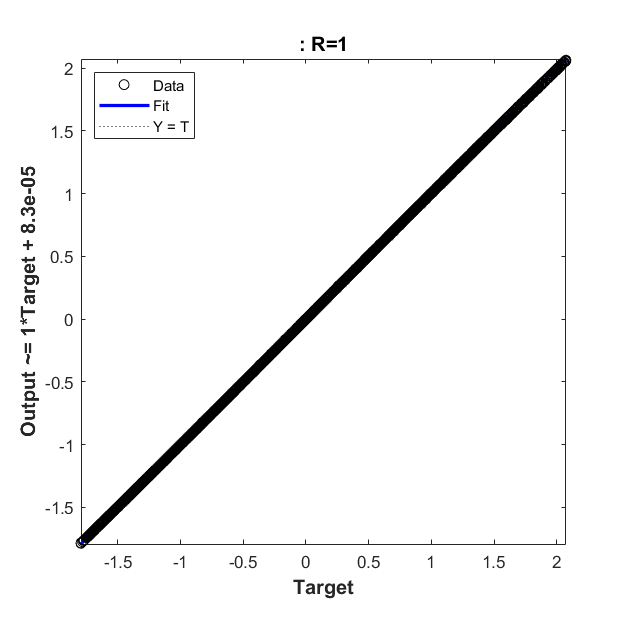

plotregression(Y_test',Y_pred);